load("Vessel connectivity/length density pertub saccharinum.mat")

VC properties

tot_len = numel(CG);
P12 = zeros(1, length(tot_len));
P50 = zeros(1, length(tot_len));
P88 = zeros(1, length(tot_len));
for i = 1 : size(PLC,2)
    if max(PLC(:,i)) > 0
        zeroLast = find(PLC(:,i) == 0,1,'last');
        oneFirst = find(PLC(:,i) == max(PLC(:,i)),1,'first');
        PLCunique = PLC(zeroLast:oneFirst,i);
        Pressuresunique = Pressures(zeroLast:oneFirst,i);
        [~,ia,~]=unique(PLCunique);
        PLCunique = PLCunique(ia);
        Pressuresunique = Pressuresunique(ia);
        
        P12(i) = interp1(PLCunique, Pressuresunique, 12,...
            'linear');
        P50(i) = interp1(PLCunique, Pressuresunique, 50,...
            'linear');
        P88(i) = interp1(PLCunique, Pressuresunique, 88,...
            'linear');
    end
end

Extract Lens data

lensPit = readtable('..\tabula-Lens et al. - 2011  tables.xlsx','Sheet',1, 'PreserveVariableNames',true);
lensTissue = readtable('..\tabula-Lens et al. - 2011  tables.xlsx','Sheet',2, 'PreserveVariableNames',true);
species = lensPit{:,1};
mean_pit_array = zeros(size(lensPit, 1), size(lensPit, 2) - 1);
error_pit_array = zeros(size(lensPit, 1), size(lensPit, 2) - 1);
for i = 2 : size(lensPit,2)
    for j = 1 : size(lensPit,1)
        mean_error = split(lensPit{j, i}, '±');
        mean_pit_array(j, i-1) = str2double(mean_error{1});
        error_pit_array(j, i-1) = str2double(mean_error{2});
    end
end

mean_tissue_array = zeros(size(lensTissue, 1), size(lensTissue, 2) - 1);
error_tissue_array = zeros(size(lensTissue, 1), size(lensTissue, 2) - 1);

for i = 2 : size(lensTissue,2)
    for j = 1 : size(lensTissue,1)
        mean_error = split(lensTissue{j, i}, '±');
        mean_tissue_array(j, i-1) = str2double(mean_error{1});
        error_tissue_array(j, i-1) = str2double(mean_error{2});
    end
end

meanLens = array2table([mean_pit_array mean_tissue_array]);
varNames = [lensPit.Properties.VariableNames(2:end) lensTissue.Properties.VariableNames(2:end)];
meanLens.Properties.VariableNames = varNames;
meanLens.Properties.RowNames = species;

errorLens = array2table([error_pit_array error_tissue_array]);
errorLens.Properties.VariableNames = varNames;
errorLens.Properties.RowNames = species;

Range of GI, Dv, and Lv values simulated

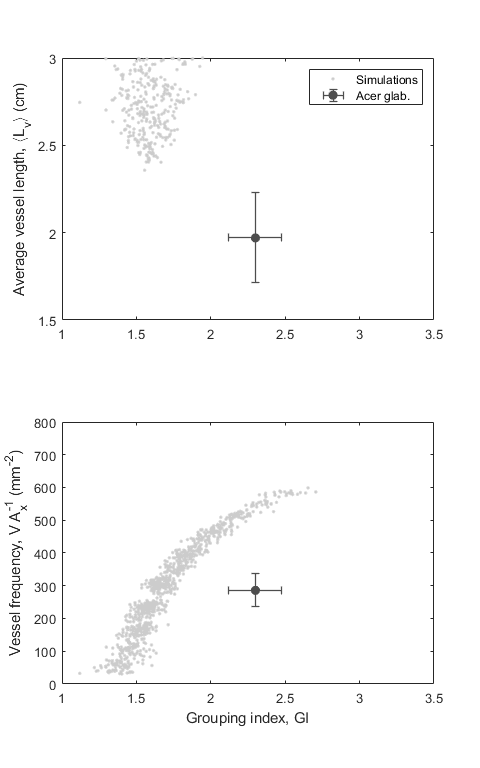

f1 = figure("Units","inches","Position",[0 0 5 8]);

subplot(2,1, 1)
plot(gi_val(~simulationNotCompleted & VAx > 30), Ls(~simulationNotCompleted & VAx > 30) * 1e2, ...
    '.', 'Color', [0.8 0.8 0.8])
hold on 
errorbar(meanLens.GI('Acer glabrum var. glabrum'),...
    meanLens.Lv('Acer glabrum var. glabrum') * 1e2,...
    errorLens.Lv('Acer glabrum var. glabrum') * 1e2,...
    errorLens.Lv('Acer glabrum var. glabrum')  * 1e2, ...
    errorLens.GI('Acer glabrum var. glabrum'),...
    errorLens.GI('Acer glabrum var. glabrum'), 'o', 'Color', [0.3 0.3 0.3], 'MarkerFaceColor', 'auto', ...
    'LineWidth', 1)
xlim([1 3.5])
ylim([1.5 3])
legend('Simulations', 'Acer glab.')
% xlabel('Grouping index')
ylabel('Average vessel length, \langleL_{v}\rangle (cm)')

subplot(2,1, 2)
plot(gi_val(~simulationNotCompleted & VAx > 30), VAx(~simulationNotCompleted & VAx > 30), ...
    '.', 'Color', [0.8 0.8 0.8])
hold on 
errorbar(meanLens.GI('Acer glabrum var. glabrum'), ...
    meanLens.('V Ax-1')('Acer glabrum var. glabrum'), ...
    errorLens.('V Ax-1')('Acer glabrum var. glabrum'), ...
    errorLens.('V Ax-1')('Acer glabrum var. glabrum'), ...
    errorLens.GI('Acer glabrum var. glabrum'), ...
    errorLens.GI('Acer glabrum var. glabrum'),'o', 'Color', [0.3 0.3 0.3], 'MarkerFaceColor', 'auto', ...
    'LineWidth', 1)
xlim([1 3.5])
ylim([0 800])
xlabel('Grouping index, GI')
ylabel('Vessel frequency, V A_{x}^{-1} (mm^{-2})')


% subplot(3,1, 2)
% plot(gi_val(~simulationNotCompleted & VAx > 30),...
%     Dcs(~simulationNotCompleted & VAx > 30) * 1e6, ...
%     '.', 'Color', [0.8 0.8 0.8])
% hold on 
% errorbar(meanLens.GI, meanLens.Dv, errorLens.Dv, errorLens.Dv, ...
%     errorLens.GI, errorLens.GI,'o', 'Color', [0.3 0.3 0.3], 'MarkerFaceColor', 'auto', ...
%     'LineWidth', 1)
% xlim([1 5])
% ylabel('Average conduit diameter (\mum)')



How connectivity, percThresh and GI and Lv relate

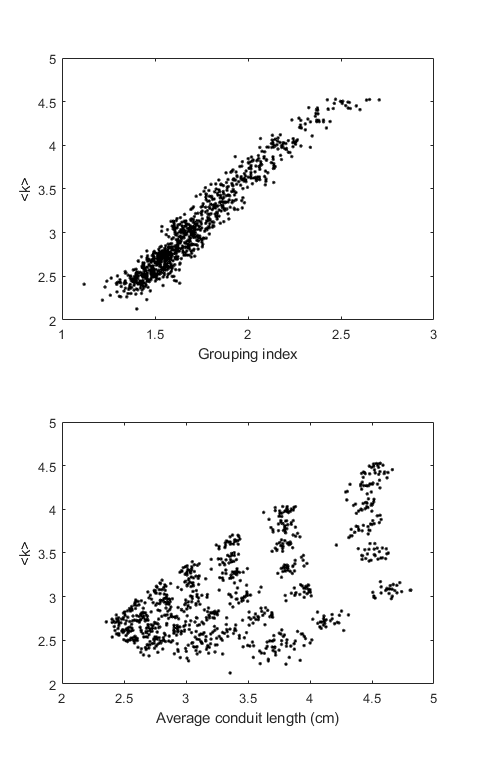

percThresh = 1 ./ ((deg_2_avg(~simulationNotCompleted) - deg_avg(~simulationNotCompleted))./deg_avg(~simulationNotCompleted));
cut_off = 6; % index of embNb to divide by its value at end.
P_cut_off = cut_off * stepSize;

f2 = figure("Units","inches","Position",[0 0 5 8]);
subplot(2,1,1)
plot(gi_val(~simulationNotCompleted & VAx > 30), deg_avg(~simulationNotCompleted & VAx > 30), 'k.')
xlabel('Grouping index')
ylabel("<k>")

subplot(2,1,2)
plot(Ls(~simulationNotCompleted & VAx > 30) * 1e2, deg_avg(~simulationNotCompleted & VAx > 30), 'k.')
xlabel('Average conduit length (cm)')
ylabel("<k>")

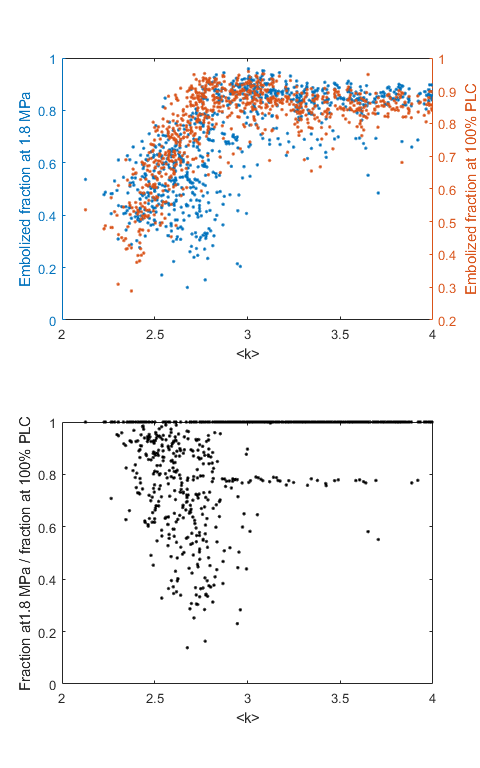


f3 = figure("Units","inches","Position",[0 0 5 8]);
subplot(2,1,1)
yyaxis left
plot(deg_avg(~simulationNotCompleted & VAx > 30),...
    embNb(cut_off,~simulationNotCompleted & VAx > 30), '.')
xlim([2 4])
xlabel('<k>')
ylabel(strcat('Embolized fraction at', {' '},num2str(P_cut_off),' MPa'))
yyaxis right
plot(deg_avg(~simulationNotCompleted & VAx > 30), embNb(end,~simulationNotCompleted & VAx > 30), '.')
% xlabel('<k>')
ylabel('Embolized fraction at 100% PLC')

subplot(2,1,2)
plot(deg_avg(~simulationNotCompleted & VAx > 30), ...
    embNb(cut_off,~simulationNotCompleted & VAx > 30) ./ embNb(end,~simulationNotCompleted & VAx > 30), 'k.')
xlim([2 4])
xlabel('<k>')
ylabel(strcat('Fraction at ',num2str(P_cut_off),' MPa / fraction at 100% PLC'))


fprime = figure("Units","inches","Position",[0 0 5 4]);

% plot(deg_avg(~simulationNotCompleted),  ktot_xa(~simulationNotCompleted).*1e6/1e3, '.')

What about perc threshold?

% figure.
% plot(gi_val(~simulationNotCompleted), percThresh , 'k.')
% xlabel('Grouping index')
% ylabel('Percolation threshold')
% 
% plot(gi_val(~simulationNotCompleted), embNb(end,~simulationNotCompleted) , 'k.')
% xlabel('Grouping index')
% ylabel('Percolation threshold')

Relation between <k>, GI with P50

f4 = figure("Units","inches","Position",[0 0 5 8]);
% subplot(2,1,1)
% plot(deg_avg(~simulationNotCompleted), P50(~simulationNotCompleted), 'k.')
% xlabel('<k>')
% ylabel('P50 (MPa)')
% 
subplot(2,1,1)
plot(gi_val(~simulationNotCompleted), P50(~simulationNotCompleted), ...
    '.', 'Color', [0.8 0.8 0.8])
hold on
plot(gi_val(~simulationNotCompleted & Ls>0.0195 & Ls<0.0205 & VAx > 30), ...
    P50(~simulationNotCompleted & Ls>0.0195 & Ls<0.0205 & VAx > 30), ...
    'rs', 'MarkerFaceColor', 'auto', 'MarkerSize', 3)
plot(gi_val(~simulationNotCompleted & Ls>0.0235 & Ls<0.0255 & VAx > 30), ...
    P50(~simulationNotCompleted & Ls>0.0235 & Ls<0.0255 & VAx > 30), ...
    's', 'Color', [1 0.5 0], 'MarkerFaceColor', 'auto', 'MarkerSize', 3)
errorbar(meanLens.GI('Acer glabrum var. glabrum'),...
    meanLens.P50('Acer glabrum var. glabrum'),...
    errorLens.P50('Acer glabrum var. glabrum'),...
    errorLens.P50('Acer glabrum var. glabrum'), ...
    errorLens.GI('Acer glabrum var. glabrum'),...
    errorLens.GI('Acer glabrum var. glabrum'), 'o', 'Color', [0.3 0.3 0.3], 'MarkerFaceColor', 'auto', ...
    'LineWidth', 1)
xlim([1 3.5])
% xlabel('Grouping index')
ylabel("Pressure at 50 PLC, P50 (MPa)")
legend('Simulations', '\langleL_{v}\rangle ~ 2 cm', '\langleL_{v}\rangle ~ 2.5 cm', '\it Acer glab.', 'Location', 'northwest')

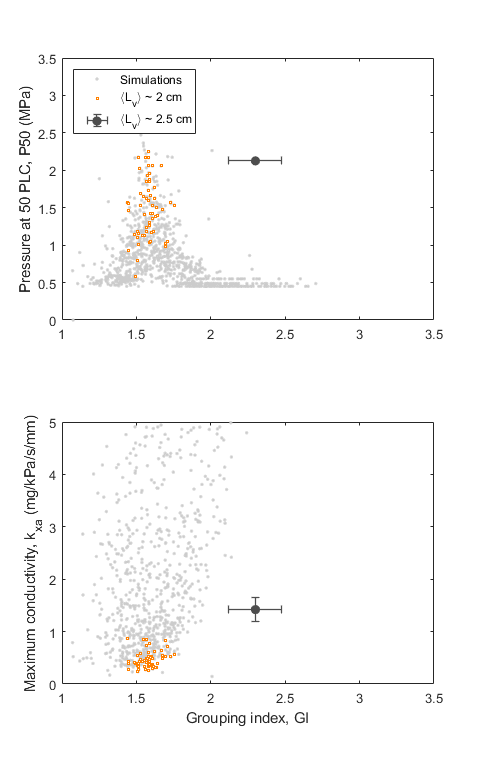

% text(meanLens.GI, meanLens.P50, strcat("         ", string(species)), ...
%     'Color', 'r' , 'FontWeight',"bold")

subplot(2,1,2)
plot(gi_val(~simulationNotCompleted), ktot_xa(~simulationNotCompleted).*1e6/1e3, ...
    '.', 'Color', [0.8 0.8 0.8]);
hold on
plot(gi_val(~simulationNotCompleted & Ls>0.0195 & Ls<0.0205 & VAx > 30), ...
    ktot_xa(~simulationNotCompleted & Ls>0.0195 & Ls<0.0205 & VAx > 30).*1e6/1e3, ...
    'rs', 'MarkerFaceColor', 'auto', 'MarkerSize', 3)
plot(gi_val(~simulationNotCompleted & Ls>0.0235 & Ls<0.0255 & VAx > 30), ...
    ktot_xa(~simulationNotCompleted & Ls>0.0235 & Ls<0.0255 & VAx > 30).*1e6/1e3, ...
    's', 'Color', [1 0.5 0], 'MarkerFaceColor', 'auto', 'MarkerSize', 3)
hold on
errorbar(meanLens.GI('Acer glabrum var. glabrum'),...
    meanLens.KXa('Acer glabrum var. glabrum'),...
    errorLens.KXa('Acer glabrum var. glabrum'),...
    errorLens.KXa('Acer glabrum var. glabrum'), ...
    errorLens.GI('Acer glabrum var. glabrum'),...
    errorLens.GI('Acer glabrum var. glabrum'), 'o', 'Color', [0.3 0.3 0.3], 'MarkerFaceColor', 'auto', ...
    'LineWidth', 1)
xlim([1 3.5])
ylim([0 5])
xlabel('Grouping index, GI')
ylabel("Maximum conductivity, k_{xa} (mg/kPa/s/mm)")

Effect of vessel lenght on kxa

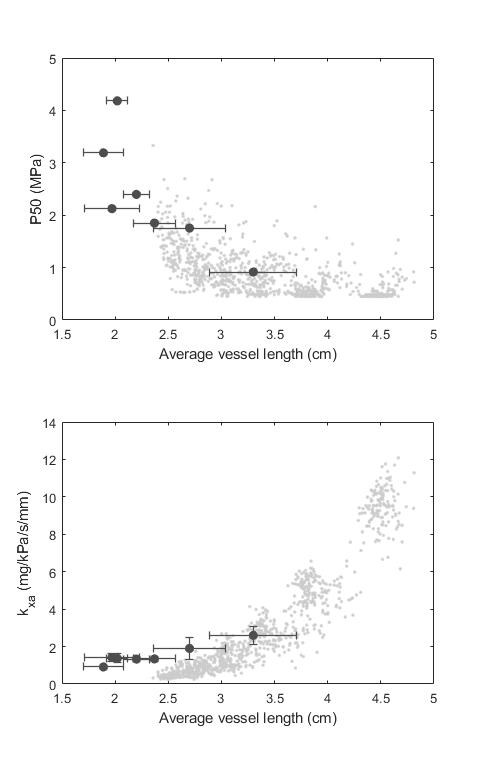

f5 = figure("Units","inches","Position",[0 0 5 8]);

subplot(2,1,1)
plot(Ls(~simulationNotCompleted & VAx > 30) * 1e2, P50(~simulationNotCompleted & VAx > 30),'.', 'Color', [0.8 0.8 0.8])
hold on
errorbar(meanLens.Lv * 1e2, meanLens.P50, errorLens.P50, errorLens.P50, ...
    errorLens.Lv * 1e2, errorLens.Lv * 1e2, 'o', 'Color', [0.3 0.3 0.3], 'MarkerFaceColor', 'auto', ...
    'LineWidth', 1)
xlabel('Average vessel length (cm)')
ylabel("P50 (MPa)")

subplot(2,1,2)
plot(Ls(~simulationNotCompleted & VAx > 30) * 1e2, ktot_xa(~simulationNotCompleted & VAx > 30) .*1e6/1e3, '.', 'Color', [0.8 0.8 0.8])
hold on
errorbar(meanLens.Lv * 1e2, meanLens.KXa, errorLens.KXa, errorLens.KXa, ...
    errorLens.Lv * 1e2, errorLens.Lv * 1e2, 'o', 'Color', [0.3 0.3 0.3], 'MarkerFaceColor', 'auto', ...
    'LineWidth', 1)
xlabel('Average vessel length (cm)')
ylabel("k_{xa} (mg/kPa/s/mm)")

### Packing 'function' (McCulloh et al. 2010 & Martinez-Vilalta et al., 2012)

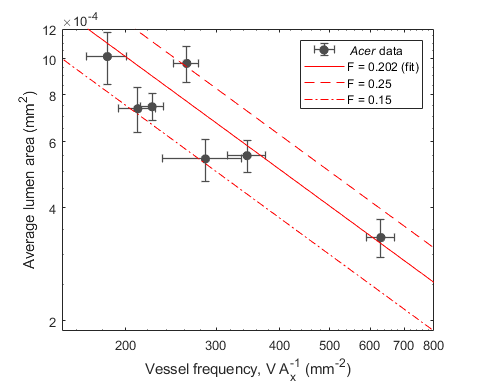

fitType = fittype('a / vax', 'independent', {'vax'}, 'coefficients', {'a'});
packing_fit = fit(meanLens.("V Ax-1"), (meanLens.Dv).^2 .* pi / 4 .* 1e-6, fitType, 'StartPoint', 0.1);

f6 = figure("Units","inches","Position",[0 0 5 4]);

errorbar(meanLens.("V Ax-1"), meanLens.ALA * 1e-6, errorLens.ALA  * 1e-6, errorLens.ALA  * 1e-6,...
    errorLens.("V Ax-1"), errorLens.("V Ax-1"), 'o', 'Color', [0.3 0.3 0.3], 'MarkerFaceColor', 'auto', ...
    'LineWidth', 1)
xlim([150 800])
ylim([0 12e-4])

hold on

vax_var = 100:800;
plot(packing_fit)
xlabel("Vessel frequency, V A_x^{-1} (mm^{-2})")
ylabel("Average lumen area (mm^2)")

hold on
plot(vax_var, 0.25./vax_var, 'r--')
plot(vax_var, 0.15./vax_var, 'r-.')
legend('{\it Acer} data','F = 0.202 (fit)', 'F = 0.25', 'F = 0.15')
% plot(vax_var, 0.25./vax_var)

% hold on 
% plot(VAx(~simulationNotCompleted & VAx > 30), pi / 4 * Dcs2(~simulationNotCompleted & VAx > 30) * 1e6,'.', 'Color', [0.8 0.8 0.8])

set(gca, 'XScale','log', 'YScale','log')

## Lumen Fraction

lumenFraction = VAx .* pi / 4 .* Dcs2 * 1e6;

Unrecognized function or variable 'Dcs2'.


f7 = figure("Units","inches","Position",[0 0 5 4]);

errorbar(meanLens.("V Ax-1"), meanLens.ALA * 1e-6, errorLens.ALA  * 1e-6, errorLens.ALA  * 1e-6,...
    errorLens.("V Ax-1"), errorLens.("V Ax-1"), 'o', 'Color', [0.3 0.3 0.3], 'MarkerFaceColor', 'auto', ...
    'LineWidth', 1)
xlim([150 800])
ylim([0 12e-4])
title('Constrain lumen fraction')

hold on

vax_var = 100:800;
plot(packing_fit)
xlabel("Vessel frequency (mm^{-2})")
ylabel("Average lumen area (mm^2)")

hold on
plot(vax_var, 0.25./vax_var, vax_var, 0.15./vax_var)
legend('Acer data','F = 0.202 (fit)', 'F = 0.25', 'F = 0.15')
% plot(vax_var, 0.25./vax_var)

hold on 
plot(VAx(lumenFraction > 0.15 & lumenFraction < 0.25),...
    pi / 4 * Dcs2(lumenFraction > 0.15 & lumenFraction < 0.25) * 1e6,'.', 'Color', [0.8 0.8 0.8])

Same figures as before but with lumen fraction constrained

constLumFrac = lumenFraction > 0.15 & lumenFraction < 0.17;
f8 = figure("Units","inches","Position",[0 0 5 8]);
% subplot(2,1,1)
% plot(deg_avg(~simulationNotCompleted), P50(~simulationNotCompleted), 'k.')
% xlabel('<k>')
% ylabel('P50 (MPa)')
% 
subplot(2,1,1)
plot(gi_val(~simulationNotCompleted & VAx > 30),...
    P50(~simulationNotCompleted & VAx > 30), ...
    '.', 'Color', [0.8 0.8 0.8])
hold on
plot(gi_val(constLumFrac),...
    P50(constLumFrac), ...
    'rs', 'MarkerFaceColor', 'auto', 'MarkerSize', 3)
errorbar(meanLens.GI, meanLens.P50, errorLens.P50, errorLens.P50, ...
    errorLens.GI, errorLens.GI, 'o', 'Color', [0.3 0.3 0.3], 'MarkerFaceColor', 'auto', ...
    'LineWidth', 1)
xlim([1 4])
% xlabel('Grouping index')
ylabel("P50 (MPa)")
legend('MC simulation', '0.15<F<0.25', '\it Acer')
% text(meanLens.GI, meanLens.P50, strcat("         ", string(species)), ...
%     'Color', 'r' , 'FontWeight',"bold")

subplot(2,1,2)
plot(gi_val(~simulationNotCompleted & VAx > 30),...
    ktot_xa(~simulationNotCompleted & VAx > 30).*1e6/1e3, ...
    '.', 'Color', [0.8 0.8 0.8]);
hold on
plot(gi_val(constLumFrac), ...
    ktot_xa(constLumFrac).*1e6/1e3, ...
    'rs', 'MarkerFaceColor', 'auto', 'MarkerSize', 3)
hold on
errorbar(meanLens.GI, meanLens.KXa, errorLens.KXa, errorLens.KXa, ...
    errorLens.GI, errorLens.GI, 'o', 'Color', [0.3 0.3 0.3], 'MarkerFaceColor', 'auto', ...
    'LineWidth', 1)
xlim([1 4])
ylim([0 5])
xlabel('Grouping index')
ylabel("k_{xa} (mg/kPa/s/mm)")

f9 = figure("Units","inches","Position",[0 0 5 4]);
plot(lumenFraction(VAx > 30), P50(VAx > 30),'.')
xlim([0.18 0.19])